repoRoot = pwd;
scriptFile = mfilename('fullpath');
try
    activeFile = matlab.desktop.editor.getActiveFilename;
catch
    activeFile = '';
end
if ~isempty(activeFile)
    scriptFile = activeFile;
end
candidateRoots = {pwd};
if ~isempty(scriptFile)
    scriptFolder = fileparts(scriptFile);
    candidateRoots = [candidateRoots, {scriptFolder, fileparts(scriptFolder)}];
end
for rootIdx = 1:numel(candidateRoots)
    if exist(fullfile(candidateRoots{rootIdx}, 'README.md'), 'file') == 2
        repoRoot = candidateRoots{rootIdx};
        break
    end
end
workspaceRoot = fileparts(fileparts(fileparts(repoRoot)));
addpath(fullfile(workspaceRoot, 'buildLib'));
addpath(fullfile(repoRoot, 'lib'));
addpath(fullfile(workspaceRoot, 'forward_solver', 'mex'));

required_cfg_fields = {'c0', 'mu0', 'eps0', 'Nx', 'Ny', 'dx', 'dy', 'dt', 'Nt', 'grid', 'pml', 'source', 'antennas', 'opts'};
if exist('cfg', 'var') ~= 1 || ~isstruct(cfg)
    error('time_reversal_practical:MissingCfg', 'Run build_test.m first so cfg exists in the workspace.');
end
for required_idx = 1:numel(required_cfg_fields)
    if ~isfield(cfg, required_cfg_fields{required_idx})
        error('time_reversal_practical:MissingCfgField', 'cfg.%s is required.', required_cfg_fields{required_idx});
    end
end
if exist('fdtd_mex', 'file') ~= 3
    error('time_reversal_practical:MissingFdtdMex', ...
        'Build forward_solver/mex/fdtd_mex before running this workflow.');
end

required_grid_fields = {'sizeXY', 'spacingXY', 'background', 'epsr', ...
    'murx', 'mury', 'cond_e', 'cond_m'};
for required_idx = 1:numel(required_grid_fields)
    if ~isfield(cfg.grid, required_grid_fields{required_idx})
        error('time_reversal_practical:MissingGridField', 'cfg.grid.%s is required.', required_grid_fields{required_idx});
    end
end
required_pml_fields = {'condx', 'condy', 'kx', 'ky'};
for required_idx = 1:numel(required_pml_fields)
    if ~isfield(cfg.pml, required_pml_fields{required_idx})
        error('time_reversal_practical:MissingPmlField', ...
            'cfg.pml.%s is required.', required_pml_fields{required_idx});
    end
end
if ~isfield(cfg.source, 'location') || isempty(cfg.source.location) || ...
        ~isfield(cfg.source, 'func') || ~isa(cfg.source.func, 'function_handle')
    error('time_reversal_practical:MissingSource', ...
        'cfg.source.location and cfg.source.func are required.');
end

grid_size = cfg.grid.sizeXY(:).';
if numel(grid_size) ~= 2 || any(grid_size < 3) || any(grid_size ~= round(grid_size))
    error('time_reversal_practical:InvalidGridSize', 'cfg.grid.sizeXY must contain two integer dimensions, each at least 3.');
end
if ~isfield(cfg.antennas, 'pos') || isempty(cfg.antennas.pos)
    error('time_reversal_practical:MissingAntennas', 'cfg.antennas.pos is required.');
end
antennas = cfg.antennas;
if size(antennas.pos, 2) ~= 2 || any(~isfinite(antennas.pos(:))) || any(antennas.pos(:) ~= round(antennas.pos(:)))
    error('time_reversal_practical:InvalidAntennaPositions', 'cfg.antennas.pos must be an Nant-by-2 integer coordinate array.');
end
if any(antennas.pos(:,1) < 1) || any(antennas.pos(:,1) > grid_size(1)) || any(antennas.pos(:,2) < 1) || any(antennas.pos(:,2) > grid_size(2))
    error('time_reversal_practical:AntennaOutOfBounds', 'All antenna positions must lie inside the grid.');
end

Nant = size(antennas.pos, 1);
antennas.numAntennas = Nant;
cfg.antennas = antennas;

if ~isfield(cfg.antennas, 'txAntennas') || isempty(cfg.antennas.txAntennas)
    error('time_reversal_practical:MissingTxAntennas', ...
        'cfg.antennas.txAntennas must select at least one transmitter.');
end
tx_antenna = cfg.antennas.txAntennas(1);
control_default = @(value) value;

remove_tx_channel = control_default(false);
apply_temporal_window = control_default(true);
temporal_window_tau = 20e-12;
normalize_receiver_traces = control_default(false);
store_forward_histories = true;%control_default(false);
store_tr_history = true; %control_default(true);
tr_history_stride = 5;
show_tr_animation = control_default(true);
tr_animation_pause = 0.01;
show_receiver_traces = control_default(true);
show_tr_image = control_default(true);
use_incident_medium_for_tr = control_default(true);
use_absorbing_pml_for_tr = true;

clear control_default
cfg.sizeZ = 1;
cfg.snapshotStart = 0;
cfg.snapshotStride = 0;
if store_forward_histories
    cfg.snapshotStride = 1;
end
cfg.returnEz = logical(store_forward_histories);
cfg.returnHx = false;
cfg.returnHy = false;
cfg.returnRxSignals = true;
source_waveform = cfg.source.func((0:cfg.Nt-1) .* cfg.dt);
source_waveform = source_waveform(:).';
source_samples = zeros(Nant, cfg.Nt);
source_samples(tx_antenna, :) = source_waveform;
cfg.source.samples = source_samples;

incident_cfg = fdtdmat.setBackgroundDefault(cfg, cfg.grid.background);
if isfield(incident_cfg, 'targets')
    incident_cfg.targets = struct([]);
end
fprintf('Running total-field MEX propagation...\n');
result_tot = fdtd_mex(cfg);

fprintf('Running incident-field MEX propagation...\n');

Transmitting from antenna 12/23...


result_inc = fdtd_mex(incident_cfg);

Transmitting from antenna 12/23...



if ~isfield(result_tot, 'rx_signals') || ~isfield(result_inc, 'rx_signals')
    error('time_reversal_practical:MissingReceiverSignals', 'Forward MEX runs must return result.rx_signals.');
end
if ~isequal(size(result_tot.rx_signals), size(result_inc.rx_signals))
    error('time_reversal_practical:ReceiverSizeMismatch', 'Total and incident receiver signals must have the same size.');
end

rx_scat = result_tot.rx_signals - result_inc.rx_signals;
tr_data = rx_scat;
if remove_tx_channel
    tr_data(tx_antenna, :) = 0;
end

tr_data_unwindowed = tr_data;
time_s = (0:size(tr_data, 2)-1) .* cfg.dt;
temporal_window = ones(size(tr_data));
temporal_window_peak_index = ones(size(tr_data, 1), 1);
temporal_window_peak_time = zeros(size(tr_data, 1), 1);

if apply_temporal_window
    for rx_idx = 1:size(tr_data, 1)
        if any(tr_data(rx_idx, :) ~= 0)
            [~, temporal_window_peak_index(rx_idx)] = max(abs(tr_data(rx_idx, :)));
            temporal_window_peak_time(rx_idx) = time_s(temporal_window_peak_index(rx_idx));
            for sample_idx = 1:size(tr_data, 2)
                temporal_window(rx_idx, sample_idx) = ...
                    exp(-((time_s(sample_idx) - temporal_window_peak_time(rx_idx)) ./ temporal_window_tau).^2);
                tr_data(rx_idx, sample_idx) = tr_data(rx_idx, sample_idx) .* temporal_window(rx_idx, sample_idx);
            end
        end
    end
end

tr_data_rev = fliplr(tr_data);

if normalize_receiver_traces
    trace_scale = max(abs(tr_data_rev), [], 2);
    trace_scale(trace_scale == 0) = 1;
    tr_data_rev = tr_data_rev ./ trace_scale;
end

if store_forward_histories
    E_tot = result_tot.Ez;
    E_inc = result_inc.Ez;
    E_scat = E_tot - E_inc;
end

if use_incident_medium_for_tr
    tr_cfg = incident_cfg;
else
    tr_cfg = cfg;
end

if ~isfield(antennas, 'doiMask') || isempty(antennas.doiMask)
    error('time_reversal_practical:MissingDOIMask', ...
        'cfg.antennas.doiMask must be provided by the antenna builder.');
end
focus_doi_mask = antennas.doiMask ~= 0;
tr_pml_pixels = nnz(cfg.pml.condx ~= 0 | cfg.pml.condy ~= 0);

fprintf('Running time-reversal MEX propagation...\n');
tr_cfg.source.samples = tr_data_rev;
tr_cfg.snapshotStart = 0;
tr_cfg.snapshotStride = 1;
tr_cfg.returnEz = true;
tr_cfg.returnHx = false;
tr_cfg.returnHy = false;
tr_cfg.returnRxSignals = true;
tr_mex_result = fdtd_mex(tr_cfg, true);
tr_result = analyzeTimeReversal(tr_mex_result, focus_doi_mask, ...
    store_tr_history, tr_history_stride);
image_max = tr_result.image_max;
Ez_reversed = tr_result.Ez_reversed;
tr_focus_mag_image = tr_result.focus_mag_image;
tr_focus_mag_Ez = tr_result.focus_mag_Ez;
tr_focus_mag_step = tr_result.focus_mag_step;
tr_focus_mag_peak_value = tr_result.focus_mag_peak_value;
tr_focus_entropy_image = tr_result.focus_entropy_image;
tr_focus_entropy_Ez = tr_result.focus_entropy_Ez;
tr_focus_entropy_step = tr_result.focus_entropy_step;
tr_focus_entropy_value = tr_result.focus_entropy_value;
if isfield(tr_result, 'Ez_reversed_all')
    Ez_reversed_all = tr_result.Ez_reversed_all;
    tr_history_steps = tr_result.history_steps;
end
tr_summary = table(max(image_max(:)), tr_focus_mag_peak_value, tr_focus_mag_step, tr_focus_entropy_value, tr_focus_entropy_step, nnz(focus_doi_mask), remove_tx_channel, apply_temporal_window, temporal_window_tau * 1e12, normalize_receiver_traces, use_incident_medium_for_tr, use_absorbing_pml_for_tr, tr_pml_pixels, string(tr_result.loss_mode), ...
    'VariableNames', {'PeakImageValue', 'FocusMagPeakDOI', 'FocusMagStep', 'FocusEntropyR', 'FocusEntropyStep', 'DOIPixels', 'RemovedTxChannel', 'TemporalWindow', 'WindowTauPs', 'NormalizedTraces', 'UsedIncidentMedium', 'AbsorbingPML', 'PMLPixels', 'LossMode'});
disp(tr_summary);
if show_receiver_traces
    time_ns = (0:size(rx_scat, 2)-1) * cfg.dt * 1e9;
    figure;
    tiledlayout(3, 1)
    nexttile
    plot(time_ns, rx_scat.')
    grid on
    xlabel('Time [ns]')
    ylabel('E_z scattered')

Running TR propagation for 800 steps in receiverInjection mode...


    title('Raw scattered receiver traces')
    nexttile
    plot(time_ns, tr_data.')
    grid on
    xlabel('Time [ns]')
    ylabel('E_z windowed')
    title('Windowed TR input traces')
    nexttile
    plot(time_ns, tr_data_rev.')
    grid on
    xlabel('Time [ns]')
    ylabel('E_z^{TR}')
    title('Time-reversed injection traces')
end
if show_tr_image
    figure;
    tiledlayout(1, 2)

    theta_tr = linspace(0, 2*pi, 256);
    focus_plot_images = {tr_focus_mag_image, tr_focus_entropy_image};
    focus_plot_titles = { ...
        sprintf('Max magnitude focus frame: |E_z^{TR}(x,y,t_%d)|^2', tr_focus_mag_step), ...
        sprintf('Minimum R focus frame: |E_z^{TR}(x,y,t_%d)|^2', tr_focus_entropy_step)};


    PeakImageValue    FocusMagPeakDOI    FocusMagStep    FocusEntropyR    FocusEntropyStep    DOIPixels    RemovedTxChannel    TemporalWindow    WindowTauPs    NormalizedTraces    UsedIncidentMedium    AbsorbingPML    PMLPixels    LossMode
    ______________    _______________    ____________    _____________    ________________    _________    ________________    ______________    ___________    ________________    __________________    ____________    _________    ________

      7.5646e-06        6.3615e-06         

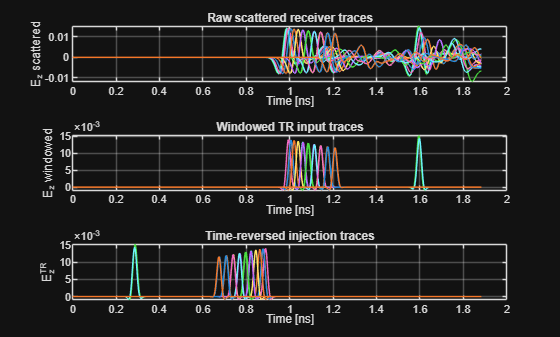

    focus_plot_max = max([tr_focus_mag_image(:); tr_focus_entropy_image(:)]);

    for focus_plot_idx = 1:2
        nexttile
        imagesc(focus_plot_images{focus_plot_idx}')
        axis equal tight
        set(gca, 'YDir', 'normal')
        colorbar
        if focus_plot_max > 0 && isfinite(focus_plot_max)
            clim([0 focus_plot_max])
        end
        hold on
        plot(antennas.pos(:,1), antennas.pos(:,2), 'wo', 'MarkerSize', 7, 'LineWidth', 1.5)
        tx_pos_tr = antennas.pos(tx_antenna, :);
        plot(tx_pos_tr(1), tx_pos_tr(2), 'rx', 'MarkerSize', 12, 'LineWidth', 2.5)
        contour(double(focus_doi_mask'), [0.5 0.5], 'c--', 'LineWidth', 1.25)

        for target_idx = 1:numel(cfg.targets)
            target = cfg.targets(target_idx);
            switch string(target.name)
                case "circle"
                    plot(target.properties.center(1) + target.properties.radius*cos(theta_tr), ...
                        target.properties.center(2) + target.properties.radius*sin(theta_tr), ...

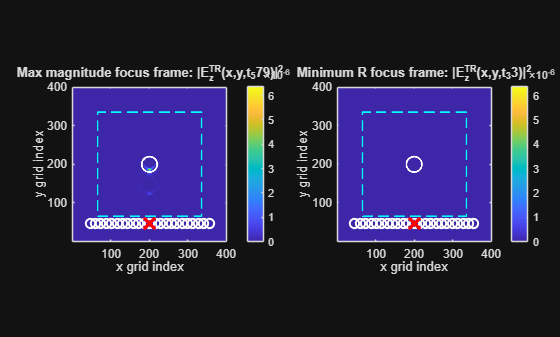

                        'w-', 'LineWidth', 1.5)
                case "rectangle"
                    bounds = target.properties.bounds;
                    plot([bounds(1), bounds(2), bounds(2), bounds(1), bounds(1)], ...
                        [bounds(3), bounds(3), bounds(4), bounds(4), bounds(3)], ...
                        'w-', 'LineWidth', 1.5)
                case "triangle"
                    vertices = [target.properties.vertices; target.properties.vertices(1, :)];
                    plot(vertices(:, 1), vertices(:, 2), 'w-', 'LineWidth', 1.5)
            end
        end

        hold off
        title(focus_plot_titles{focus_plot_idx})
        xlabel('x grid index')
        ylabel('y grid index')
    end
end
if show_tr_animation
    if exist('Ez_reversed_all', 'var') ~= 1 || isempty(Ez_reversed_all)
        warning('time_reversal_practical:MissingTrMovie', 'Set store_tr_history = true and rerun the TR computation to create Ez_reversed_all.');
    else
        if exist('tr_history_steps', 'var') ~= 1 || numel(tr_history_steps) ~= size(Ez_reversed_all, 3)
            tr_history_steps = 1:size(Ez_reversed_all, 3);
        end
        movie_clim = max(abs(Ez_reversed_all(:)));
        if movie_clim == 0 || ~isfinite(movie_clim)
            movie_clim = 1;
        end
        figure;
        for movie_idx = 1:size(Ez_reversed_all, 3)
            imagesc(Ez_reversed_all(:, :, movie_idx)')
            axis equal tight
            set(gca, 'YDir', 'normal')
            colorbar
            clim([-movie_clim movie_clim])
            title(sprintf('TR E_z playback frame %d/%d, step %d', movie_idx, size(Ez_reversed_all, 3), tr_history_steps(movie_idx)))
            xlabel('x grid index')
            ylabel('y grid index')
            drawnow
            pause(tr_animation_pause)
        end
    end
end

function result = analyzeTimeReversal(mexResult, focusMask, storeHistory, historyStride)
%analyzeTimeReversal Compute focusing products from the complete MEX Ez history.

EzAll = mexResult.Ez;
numSteps = size(EzAll, 3);
imageMax = zeros(size(focusMask));

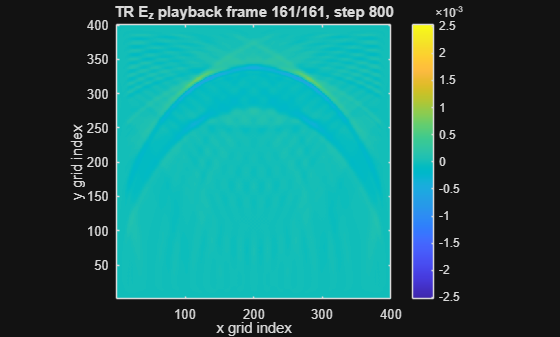

focusMagImage = zeros(size(focusMask));
focusMagEz = zeros(size(focusMask));
focusMagPeakValue = -inf;
focusMagStep = 1;
focusEntropyImage = zeros(size(focusMask));
focusEntropyEz = zeros(size(focusMask));
focusEntropyValue = inf;
focusEntropyStep = 1;
entropyAbsTol = 1e-15;
entropyRelTol = 1e-12;

for step = 1:numSteps
    EzFrame = EzAll(:, :, step);
    framePower = abs(EzFrame).^2;
    imageMax = max(imageMax, framePower);
    framePeakValue = max(framePower(focusMask));
    if framePeakValue > focusMagPeakValue
        focusMagPeakValue = framePeakValue;
        focusMagStep = step;
        focusMagEz = EzFrame;
        focusMagImage = framePower;
    end
    roiAmplitude = abs(EzFrame(focusMask));
    roiPeakAmplitude = max(roiAmplitude);
    if roiPeakAmplitude > entropyAbsTol
        entropyCutoff = max(entropyAbsTol, entropyRelTol .* roiPeakAmplitude);

        validAmplitude = roiAmplitude(roiAmplitude >= entropyCutoff);
        normalizedPower = (validAmplitude ./ roiPeakAmplitude).^2;
        entropyWeights = normalizedPower ./ sum(normalizedPower);
        frameEntropyValue = 1 ./ sum(entropyWeights.^2);
    else
        frameEntropyValue = inf;
    end
    if frameEntropyValue < focusEntropyValue
        focusEntropyValue = frameEntropyValue;
        focusEntropyStep = step;
        focusEntropyEz = EzFrame;
        focusEntropyImage = framePower;
    end
end

result = struct();
result.Ez_reversed = EzAll(:, :, end);
result.image_max = imageMax;
result.tr_mode = "receiverInjection";
result.loss_mode = "native";
result.num_steps = numSteps;
result.rx_signals = mexResult.rx_signals;
result.focus_mag_image = focusMagImage;
result.focus_mag_Ez = focusMagEz;
result.focus_mag_step = focusMagStep;
result.focus_mag_peak_value = focusMagPeakValue;
result.focus_entropy_image = focusEntropyImage;
result.focus_entropy_Ez = focusEntropyEz;
result.focus_entropy_step = focusEntropyStep;
result.focus_entropy_value = focusEntropyValue;
result.focus_mask = focusMask;
if storeHistory
    historySteps = unique([1:historyStride:numSteps, numSteps]);
    result.Ez_reversed_all = EzAll(:, :, historySteps);
    result.history_steps = historySteps;
    result.history_stride = historyStride;
    result.store_magnetic_history = false;
end
end